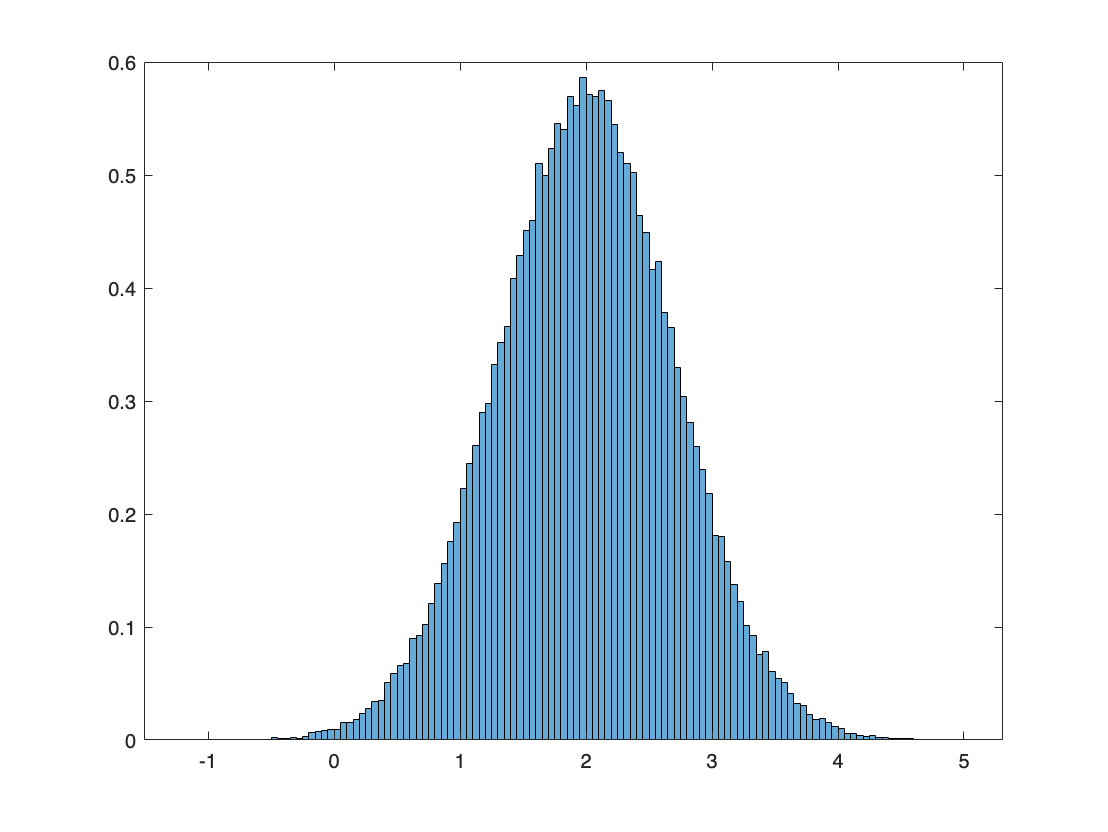

% Setting up parameters of Monte Carlo simulation
% ---------------------------------------
clc
clear all
clf

numMonteCLoops = 1E5; % Number of Monte Carlo Loops
A = 2; % True value of the parameter
sigma2 = 0.5; % Parameters for covariance of noise
rhoVals = [-1, 0, 0.5,1]; % Parameters for covariance of noise
rhoInd = 2; % Change this value from 1 to 4 to select rho value
C = [1 rhoVals(rhoInd); rhoVals(rhoInd) 1]; % defining covariance matrix
N = 2; % Number of observations
H = [1;1]; % Observation matrix

% ---------------------------------------

% Initializing variable for stability
estimate = ones(1,numMonteCLoops)*NaN;

for MC=1:numMonteCLoops

    
    if rhoInd ~= 1 && rhoInd ~= 4
        % C is non-singular
        w = mvnrnd([0 0], C);
        x = H*A + w';
        Cinv = inv(C);
        invPart = H'*Cinv*H;
        estimate(MC) = invPart*H'*Cinv*x;
    elseif rhoInd == 1
        
        % rho = -1 => C is singular but noise is reduced to ~N(0,0)
        % The estimate is the sample mean = 0.5*(x[0] + x[1])
        x = H*A + (randn(N, 1) * 0);
        estimate(MC) = mean(x);
    elseif rhoInd == 4
        
        % rho = +1 => C is singular but noise is reduced to ~N(0,1)
        % The estimate is the sample mean = 0.5*(x[0] + x[1])
        x = H*A + (randn(N, 1) * 1);
        estimate(MC) = mean(x);
    
    end
     
end

figure(1)
clf
% Drawing the Probability Density Function of the simulated estimates
histogram(estimate, 'Normalization', 'pdf');
hold on


if rhoInd ~= 1 && rhoInd ~= 4
    % C is non-singular
    matX = H'* inv(C) * H;
    var_est = inv(matX);
elseif rhoInd == 1
    
    % rho = -1 => C is singular but noise is reduced to ~N(0,0)
    % The estimate is the sample mean = 0.5*(x[0] + x[1])
    var_est = 0;
elseif rhoInd == 4
    
    % rho = +1 => C is singular but noise is reduced to ~N(0,1)
    % The estimate is the sample mean = 0.5*(x[0] + x[1])
    var_est = 1;

end
mu = mean(estimate);
disp(['Simulated Variance: ', num2str(var_est)]);

Simulated Variance: 0.5


disp(['Simulated Mean: ', num2str(mu)]);

Simulated Mean: 7.9987



% Calculation of theoretical variance

if rhoInd ~= 1 && rhoInd ~= 4
    % C is non-singular
    varTHeo1 = H'* inv(C) * H;
    varTHeo = 1/varTHeo1;
elseif rhoInd == 1
    
    % rho = -1 => C is singular but noise is reduced to ~N(0,0)
    rho = rhoVals(rhoInd);
    varTHeo = 0.5*sigma2*(1+rho);
elseif rhoInd == 4
    
    % rho = +1 => C is singular but noise is reduced to ~N(0,1)
    % The estimate is the sample mean = 0.5*(x[0] + x[1])
    rho = rhoVals(rhoInd);
    varTHeo = 0.5*sigma2*(1+rho);

end

disp(['Theoretical Variance: ', num2str(varTHeo)]);

Theoretical Variance: 0.5


disp(['Theoretical Mean: ', num2str(A)]);

Theoretical Mean: 2
